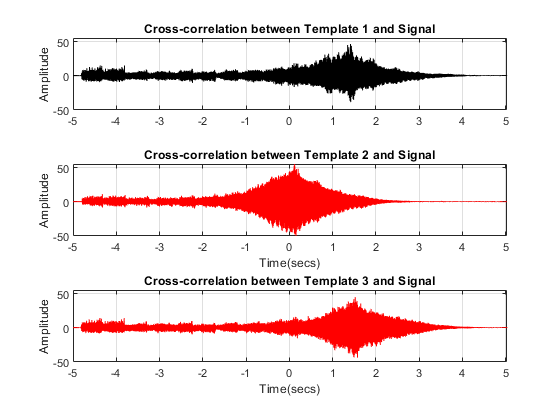

%TODO: Could make an if loop for if sampling frequency, duration and other
%properties are the same, to just create one global var instead of loads.

[S,Fs] = audioread('Music library\5 second a new beginning.mp3');

[T1,Fs1] = audioread("Music library\Recorded\Original\10 cm away.m4a");
[T2,Fs2] = audioread("Music library\Recorded\Original\50 cm away.m4a");
[T3,Fs3] = audioread("Music library\Recorded\Original\100 cm away.m4a");


%TODO: If two channels, run mean loop. 
%Create Matrix of all stats around here so one martrx/table can be
%refrenced throughout

S = mean(S,2);
T1 = mean(T1,2);
T2 = mean(T2,2);
T3 = mean(T3,2);

timeInSeconds = numel(S)/Fs;
timeInSeconds1 = numel(T1)/Fs1;
timeInSeconds2 = numel(T2)/Fs2;
timeInSeconds3 = numel(T3)/Fs3;



% plot(S(:,1))
% plot(T1(:,1))
% plot(T2(:,1))

[P1,Q1] = rat(Fs/Fs1);          % Rational fraction approximation
[P2,Q2] = rat(Fs/Fs2);          % Rational fraction approximation
[P3,Q3] = rat(Fs/Fs3);          % Rational fraction approximation

T1 = resample(T1,P1,Q1);        % Change sampling rate by rational factor
T2 = resample(T2,P2,Q2);        % Change sampling rate by rational factor
T3 = resample(T3,P3,Q3);        % Change sampling rate by rational factor


[C1,lag1] = xcorr(T1,S);        
[C2,lag2] = xcorr(T2,S);
[C3,lag3] = xcorr(T3,S);



% newC2 = [C2, zeros(size(C2, 1), size(C1, 2)-size(C2, 2)); zeros(size(C1, 1)-size(C2, 1), size(C1, 2))];

newC2 = [C2, zeros(size(C2, 1), size(C3, 2)-size(C2, 2)); zeros(size(C3, 1)-size(C2, 1), size(C3, 2))];
newC1 = [C1, zeros(size(C1, 1), size(C3, 2)-size(C1, 2)); zeros(size(C3, 1)-size(C1, 1), size(C3, 2))];

bigMatrixLol = [newC1 newC2 C3];
maxCorr = max(bigMatrixLol);
[largestCorrValue,columnOfLargest] = max(maxCorr);


figure
ax(1) = subplot(3,1,1); 
plot(lag1/Fs,C1,'k')
ylabel('Amplitude')
grid on
title('Cross-correlation between Template 1 and Signal')

ax(2) = subplot(3,1,2); 
plot(lag2/Fs,C2,'r')
ylabel('Amplitude') 
grid on
title('Cross-correlation between Template 2 and Signal')
xlabel('Time(secs)') 

ax(3) = subplot(3,1,3); 
plot(lag3/Fs,C3,'r')
ylabel('Amplitude') 
grid on
title('Cross-correlation between Template 3 and Signal')
xlabel('Time(secs)') 
% 
% ax(4) = subplot(5,1,4); 
% plot(lag4/Fs,C4,'r')
% ylabel('Amplitude') 
% grid on
% title('Cross-correlation between Template 4 and Signal')
% xlabel('Time(secs)') 
% 
% ax(5) = subplot(5,1,5); 
% plot(lag5/Fs,C5,'r')
% ylabel('Amplitude') 
% grid on
% title('Cross-correlation between Template 5 and Signal')
% xlabel('Time(secs)') 
% 
axis(ax(1:3),[-5 (timeInSeconds) (min(C2)) (max(C2)) ])


[~,I] = max(abs(C2));
SampleDiff = lag2(I);

elementsS = numel(S);
elementsT1 = numel(T1);
elementsT2 = numel(T2);
elementsT3 = numel(T3);


if elementsS > elementsT1
    diff = elementsS - elementsT1;
    indexToDeleteFrom = elementsS - diff;
    S(indexToDeleteFrom + 1:end,:) = [];
elseif elementsR50 > elementsS
    diff = elementsR50 - elementsS;
    indexToDeleteFrom = elementsR50 - diff;
    R50(indexToDeleteFrom:end,:) = [];
end



% % 
% % closestMatched = R50(SampleDiff:(numel(S) + SampleDiff -1));
% closestMatched = R50;
% 
% cc = corrcoef(S,closestMatched);
% similarityCoefficient = cc(1,2);
% 
% 
% 
% timeDiff = SampleDiff/Fs;
% 
% delay = finddelay(S,R50);
% 
% % alignedSignals = alignsignals(S,R50);
% [X Y] = alignsignals(S,R50);
% 
% % plot(alignedSignals)
% % 
% % 
% % plot(S)
% % plot(closestMatched)
% 
% %%found similarities. Now to add recordings of these songs%%